opts = spreadsheetImportOptions("NumVariables", 8);

% Specify sheet and range
opts.Sheet = "PHS list";
opts.DataRange = "A30:H376";

% Specify column names and types
opts.VariableNames = ["Var1", "Type", "Var3", "Var4", "Commissioned", "Var6", "country", "MW"];
opts.SelectedVariableNames = ["Type", "Commissioned", "country", "MW"];
opts.VariableTypes = ["char", "categorical", "char", "char", "datetime", "char", "categorical", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var3", "Var4", "Var6"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Type", "Var3", "Var4", "Var6", "country"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Commissioned", "InputFormat", "");

% Import the data
filepath = pwd;
PSlist = readtable(filepath+"\list 6.xlsx", opts, "UseExcel", false);
clear opts

PSlist.Commissioned = year(PSlist.Commissioned);
% before 1980
MWb1980 = sum(PSlist.MW(PSlist.Commissioned<1980))

MWb1980 = 5.0826e+04

% 1980 to now
PSlist2 = PSlist(PSlist.Commissioned>=1980,:);
PSlist2 = sortrows(PSlist2,"Commissioned");
MWa1980 = sum(PSlist2.MW)

MWa1980 = 1.2411e+05

MWa1980+MWb1980

ans = 1.7494e+05

% capacity and type installed after 1980
res = grpstats(PSlist2,"Type","sum","DataVars","MW");
res.perc = 100*res.sum_MW/MWa1980;

yearlyMW = grpstats(PSlist, "Commissioned", 'sum', 'DataVars','MW');
yearlyMW.Cumul = cumsum(yearlyMW.sum_MW);

temp = table();
temp.Commissioned = yearlyMW.Commissioned;

ChinaMW = PSlist(PSlist.country == "China",:);
ChinaStat = grpstats(ChinaMW, "Commissioned", 'sum', 'DataVars','MW');
ChinaStat.Cumul = cumsum(ChinaStat.sum_MW);
ChinaStat = outerjoin(temp,ChinaStat);
ChinaStat = fillmissing(ChinaStat,"previous");

JapanMW = PSlist(PSlist.country == "Japan",:);
JapanStat = grpstats(JapanMW, "Commissioned", 'sum', 'DataVars','MW');
JapanStat.Cumul = cumsum(JapanStat.sum_MW);
JapanStat = outerjoin(temp,JapanStat);
JapanStat = fillmissing(JapanStat,"previous");

IndiaMW = PSlist(PSlist.country == "India",:);
IndiaStat = grpstats(IndiaMW, "Commissioned", 'sum', 'DataVars','MW');
IndiaStat.Cumul = cumsum(IndiaStat.sum_MW);
IndiaStat = outerjoin(temp,IndiaStat);
IndiaStat = fillmissing(IndiaStat,"previous");

USMW = PSlist(PSlist.country == "United States",:);
USStat = grpstats(USMW, "Commissioned", 'sum', 'DataVars','MW');
USStat.Cumul = cumsum(USStat.sum_MW);
USStat = outerjoin(temp,USStat);
USStat = fillmissing(USStat,"previous");

AlpsMW = PSlist(ismember(PSlist.country,{'Germany','Switzerland','France','Italy','Austria'}),:);
AlpsStat = grpstats(AlpsMW, "Commissioned", 'sum', 'DataVars','MW');
AlpsStat.Cumul = cumsum(AlpsStat.sum_MW);
AlpsStat = outerjoin(temp,AlpsStat);
AlpsStat = fillmissing(AlpsStat,"previous");

IberiaMW = PSlist(ismember(PSlist.country,{'Spain','Portugal'}),:);
IberiaStat = grpstats(IberiaMW, "Commissioned", 'sum', 'DataVars','MW');
IberiaStat.Cumul = cumsum(IberiaStat.sum_MW);
IberiaStat = outerjoin(temp,IberiaStat);
IberiaStat = fillmissing(IberiaStat,"previous");

AustraliaMW = PSlist(PSlist.country == "Australia",:);
AustraliaStat = grpstats(AustraliaMW, "Commissioned", 'sum', 'DataVars','MW');
AustraliaStat.Cumul = cumsum(AustraliaStat.sum_MW);
AustraliaStat = outerjoin(temp,AustraliaStat);
AustraliaStat = fillmissing(AustraliaStat,"previous");

UKMW = PSlist(PSlist.country == "United Kingdom",:);
UKStat = grpstats(UKMW, "Commissioned", 'sum', 'DataVars','MW');
UKStat.Cumul = cumsum(UKStat.sum_MW);
UKStat = outerjoin(temp,UKStat);
UKStat = fillmissing(UKStat,"previous");

% clf; 
% hold on
% plot(yearlyMW.Commissioned,yearlyMW.Cumul)
% plot(ChinaStat.Commissioned_temp,ChinaStat.Cumul)
% plot(JapanStat.Commissioned_temp,JapanStat.Cumul)
% plot(IndiaStat.Commissioned_temp,IndiaStat.Cumul)
% plot(USStat.Commissioned_temp,USStat.Cumul)
% 
% 
% xlim([1940.3 2025.1])
% ylim([0 180000])

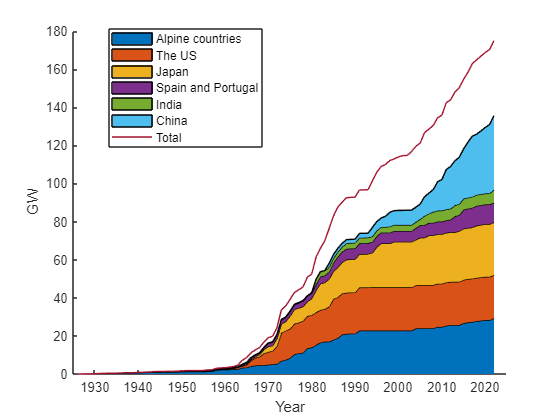

clf; hold on
area(ChinaStat.Commissioned_temp,1e-3*[AlpsStat.Cumul USStat.Cumul JapanStat.Cumul ...
    IberiaStat.Cumul IndiaStat.Cumul ChinaStat.Cumul])
plot(yearlyMW.Commissioned,1e-3*yearlyMW.Cumul)
legend("Alpine countries","The US","Japan","Spain and Portugal","India","China","Total")
ylabel("GW");xlabel("Year");

xlim([1925 2025])
% xticks([1930:10:2022])
legend('Position',[0.19492,0.67579,0.275,0.22976])